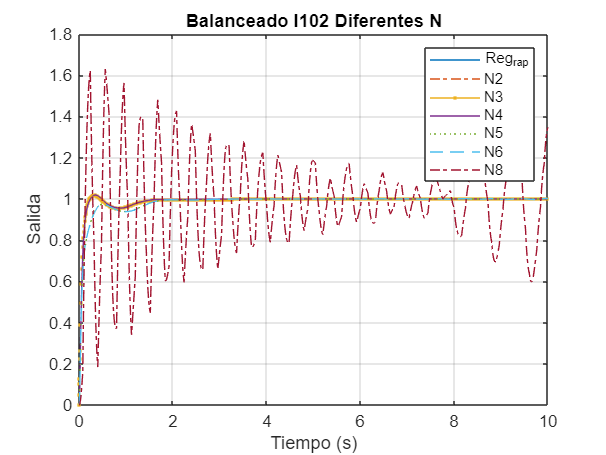

%Vehiculo
% salida yaw rate entrada steering
% El control está diseñado para considerar una velocidad lineal entre 4 y 20 m/s (circuito urbano)
%Regulador diseñado en continuo con H_inf más agresivo para modelo vehículo de Zhang
clear;
close all;
%Comparación de diferentes N

%Carga de datos
N2=load('InterlacinN2.mat');%Datos de N=2
N3=load('InterlacinN3.mat');%Datos de N=3
N4=load('InterlacinN4.mat');%Datos de N=4
N5=load('InterlacinN5.mat');%Datos de N=5
N6=load('InterlacinN6.mat');%Datos de N=6
N8=load('InterlacinN8.mat');%Datos de N=8

f=figure;
set(f,'Name','Balanceado I102')
plot(N4.datos.time,N4.datos.signals.values(:,2)),ylabel('Salida'),xlabel('Tiempo (s)'),grid
hold on;
plot(N2.datos.time,N2.datos.signals.values(:,4),'-.')
plot(N3.datos.time,N3.datos.signals.values(:,4),'.-')
plot(N4.datos.time,N4.datos.signals.values(:,4))
plot(N5.datos.time,N5.datos.signals.values(:,4),':')
plot(N6.datos.time,N6.datos.signals.values(:,4),'--')
plot(N8.datos.time,N8.datos.signals.values(:,4),'-.')
title('Balanceado I102 Diferentes N');
legend('Reg_{rap}','N2','N3','N4','N5','N6','N8')

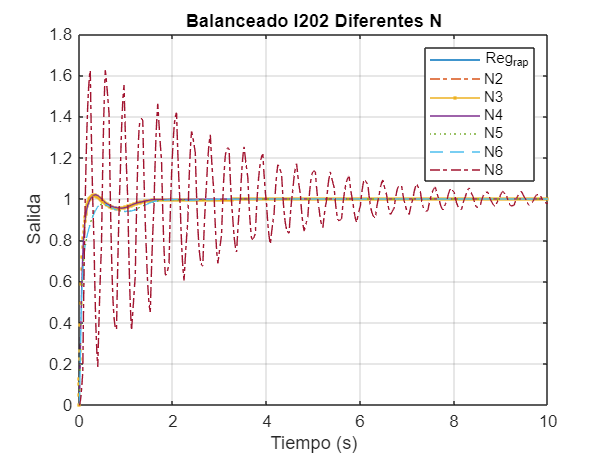


f=figure;
set(f,'Name','Balanceado I202')
plot(N4.datos.time,N4.datos.signals.values(:,2)),ylabel('Salida'),xlabel('Tiempo (s)'),grid
hold on;
plot(N2.datos.time,N2.datos.signals.values(:,4),'-.')
plot(N3.datos.time,N3.datos.signals.values(:,5),'.-')
plot(N4.datos.time,N4.datos.signals.values(:,5))
plot(N5.datos.time,N5.datos.signals.values(:,5),':')
plot(N6.datos.time,N6.datos.signals.values(:,5),'--')
plot(N8.datos.time,N8.datos.signals.values(:,5),'-.')
title('Balanceado I202 Diferentes N');
legend('Reg_{rap}','N2','N3','N4','N5','N6','N8')

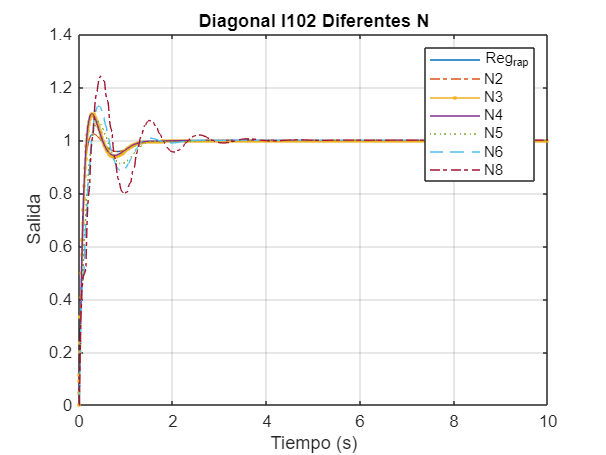


f=figure;
set(f,'Name','Diagonal I102')
plot(N4.datos.time,N4.datos.signals.values(:,2)),ylabel('Salida'),xlabel('Tiempo (s)'),grid
hold on;
plot(N2.datos.time,N2.datos.signals.values(:,4),'-.')
plot(N3.datos.time,N3.datos.signals.values(:,6),'.-')
plot(N4.datos.time,N4.datos.signals.values(:,6))
plot(N5.datos.time,N5.datos.signals.values(:,6),':')
plot(N6.datos.time,N6.datos.signals.values(:,6),'--')
plot(N8.datos.time,N8.datos.signals.values(:,6),'-.')
title('Diagonal I102 Diferentes N');
legend('Reg_{rap}','N2','N3','N4','N5','N6','N8')

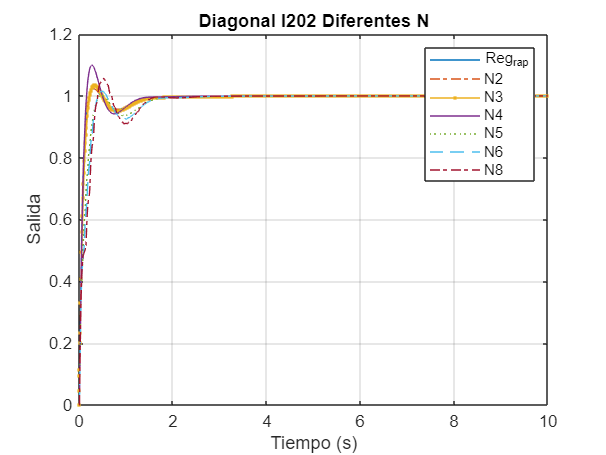


f=figure;
set(f,'Name','Diagonal I202')
plot(N4.datos.time,N4.datos.signals.values(:,2)),ylabel('Salida'),xlabel('Tiempo (s)'),grid
hold on;
plot(N2.datos.time,N2.datos.signals.values(:,4),'-.')
plot(N3.datos.time,N3.datos.signals.values(:,7),'.-')
plot(N4.datos.time,N4.datos.signals.values(:,7))
plot(N5.datos.time,N5.datos.signals.values(:,7),':')
plot(N6.datos.time,N6.datos.signals.values(:,7),'--')
plot(N8.datos.time,N8.datos.signals.values(:,7),'-.')
title('Diagonal I202 Diferentes N');
legend('Reg_{rap}','N2','N3','N4','N5','N6','N8')